Speech Waveform for the 2 seconds long 'moja' recording

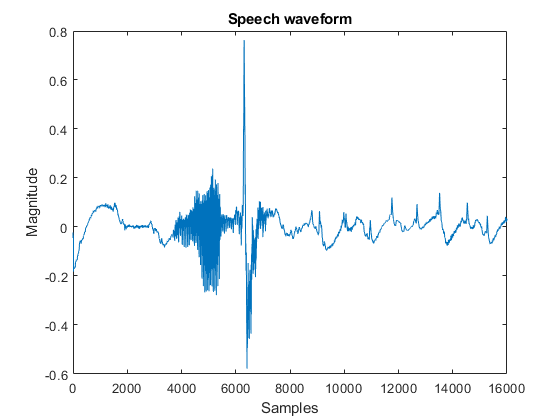

% reads data from the file named filename, and returns
% sampled data, y, and a sample rate for that data, Fs.
[y, Fs] = audioread('moja_three.wav');

% plays the audio
sound(y, Fs)

plot(y)
title('Speech waveform')
xlabel('Samples')
ylabel('Magnitude')

We will compute the spectrogram by dividing the speech signal into segments 32ms long (256 samples at 8kHz) with 50% ovelap between neighboring segments and taking the FFT of each segment. We plot the magnitude of this FFT for all the segments as a 2-dimensional image using the function specgram


% stride
alpha = 0.5;

% window size
N=256

N = 256

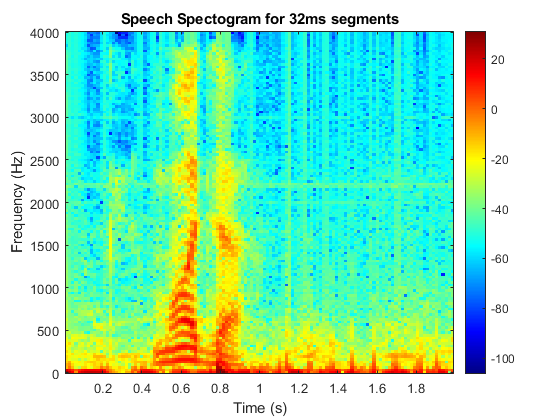


% compute a spectrogram of the audio
specgram(y(:,1),N,Fs,hamming(N),alpha*N);
colorbar
title('Speech Spectogram for 32ms segments')
xlabel('Time (s)')
ylabel('Frequency (Hz)')

Change N so that the segments are 64 ms long and plot a new spectrogram. What is the effect on the spectrogram?

period = (1/8000);
N_2 = 64e-03/period 

N_2 = 512

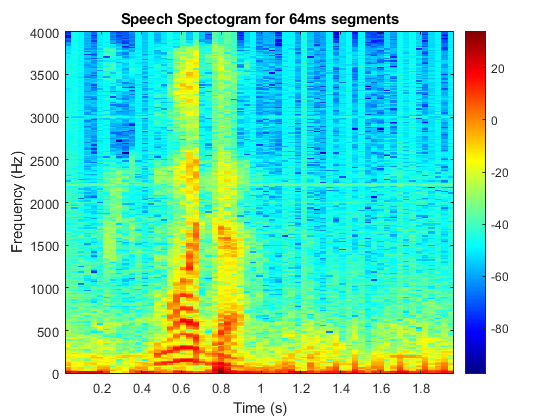

% compute a spectrogram of the audio
specgram(y(:,1),N_2,Fs,hamming(N_2),alpha*N_2);

xlabel('Time (s)')
ylabel('Frequency (Hz)')
title('Speech Spectogram for 64ms segments')
colorbar

Magnitude Spectrum of the recorded speech waveform

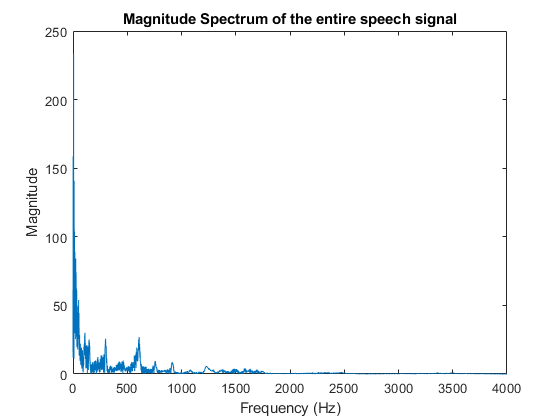

% dft of speech segment
dft_speech = fft(y);

% number of samples
n = length(y);

% frequency range
f = (0:n-1)*(Fs/n);

figure,
plot(f(1:Fs),abs(dft_speech(1:Fs)))

title('Magnitude Spectrum of the entire speech signal')
ylabel('Magnitude Spectrum')
xlabel('Frequency (Hz)')

Obtain a segment 32ms long from a region with speech and another segment of the same duration from a segment without speech and plot these time domain signals side by side with time in seconds as the x-axis. Comment on the difference between the signals. Compute and compare the energy of both signals.

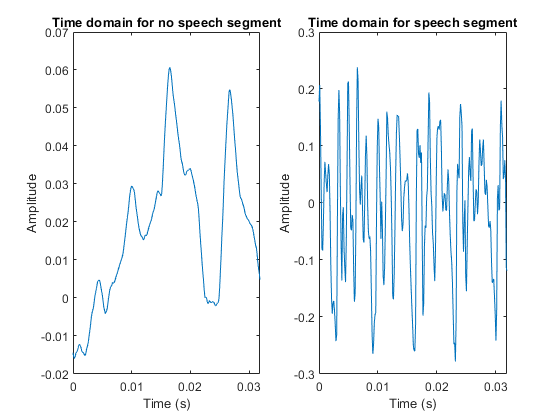

% obtaining a 32ms silent long segment/256 samples
sample_len = 32e-3*Fs;


% Start points for time domain waveforms

silence_start = 9850;
speech_start = 5100;

% obtaining a 32ms long segment/256 samples without speech
moja_sl = y(silence_start:silence_start+(sample_len-1));

% obtaining a 32ms long segment/256 samples with speech
moja_sp = y(speech_start:speech_start+(sample_len-1));

% corresponding time-length of the sample (32ms long)
t = (0:1/Fs:(length(moja_sl)-1)/Fs);

% plotting the waveforms of the segments

subplot(1,2,1)
plot(t,moja_sl)
subplot(1,2,2)
plot(t,moja_sp)

subplot(1,2,1)
title('Time domain for no speech segment')
xlabel('Time (s)')
ylabel('Amplitude')

subplot(1,2,2)
title('Time domain for speech segment')
xlabel('Time (s)')
ylabel('Amplitude')

 Compute and compare the energy of both signals.

The energy of a discrete time signal is defined as the sum of the square of the sampled signal values:


$$\mathrm{Ex}=\sum_{n=-\infty }^{\infty } \left|x{\left\lbrack n\right\rbrack }^2 \right|$$


% energy of silent segment
E_sl = sum(moja_sl.^2)

E_sl = 0.1733


% energy of speech segment
E_sp = sum(moja_sp.^2)

E_sp = 3.4409

Using the fft function, compute the DFT of both signals in (a) above and compare the frequency domain content of the signals. Plot the magnitude of the FFT versus frequency in Hz.

The Fourier transform of the signal identifies its frequency components. In MATLAB®, the [`fft`](https://www.mathworks.com/help/matlab/ref/fft.html) function computes the Fourier transform using a fast Fourier transform algorithm. Use `fft` to compute the discrete Fourier transform of the signal.

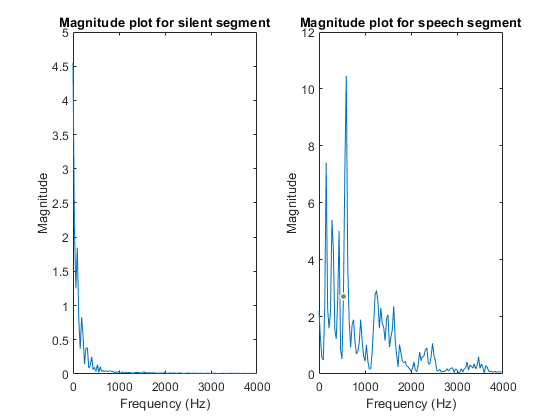

% dft of silent segment
dft_sl = fft(moja_sl);

% dft of speech segment
dft_sp = fft(moja_sp);

% number of samples
ns = length(moja_sp);

% frequency range
fs = (0:ns-1)*(Fs/ns);

subplot(1,2,1)
plot(fs(1:ns/2),abs(dft_sl(1:ns/2)))
subplot(1,2,2)
plot(fs(1:ns/2),abs(dft_sp(1:ns/2)))
% plot(f,abs(dft_sp))

subplot(1,2,1)
title('Magnitude plot for silent segment')
ylabel('Magnitude')
xlabel('Frequency (Hz)')

subplot(1,2,2)
title('Magnitude plot for speech segment')
ylabel('Magnitude')
xlabel('Frequency (Hz)')

Happy Learning,

Eric and Sam.